# Expansion of the Universe

## Task 1 

The following second-order ODE describes how the size  of the universe changes with time depending on how much matter and dark  energy is present:

d2Rdt2=−ΩM2R2+ΩDER

where R is the size of the universe, ΩM is the density of matter in the universe, and ΩDE is the density of dark energy. 

Task

Follow these steps to solve for the changing size of the universe R(t). 

-  Write a local function at the bottom of script called `@``expandingUniverse` that will solve this second-order ODE. In your local function, set the  density of matter and dark energy to 0.3 and 0.7, respectively.

-  Set the time range over which to solve the ODE between 1 and 13.1. (t = 1 corresponds to the current age of the universe.

-  Set the initial condition for the size of the universe R to 1, and the rate of expansion v to 1. Both correspond to the current size and expansion rate of the universe.

-  Solve the ODE using `ode45`. 

-  Plot the solution for size of the universe vs. `tSol`

Find and plot the size of the universe out to 13.1 times its current age. 

*Remember to define your ODE function at the bottom of the script. *

tRange=[1 13.1]

tRange =     1.0000   13.1000


Y0=[1 1]

Y0 =      1     1


[tSol,YSol]=ode45(@expandingUniverse,tRange,Y0)

tSol =     1.0000
    1.0502
    1.1005
    1.1507
    1.2010
    1.4179
    1.6348
    1.8517
    2.0686
    2.3482


YSol = 1.0e+04 *

    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0002    0.0002
    0.0002    0.0002
    0.0003    0.0002
    0.0003    0.0003


R=YSol(:,1)

R = 1.0e+04 *

    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0002
    0.0002
    0.0003
    0.0003


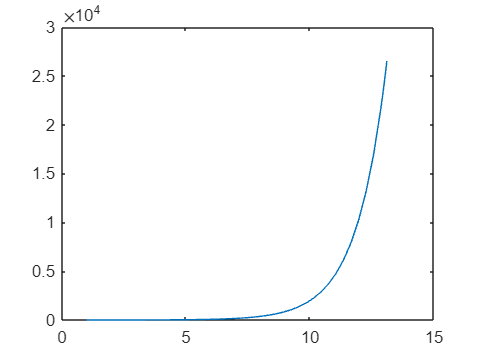

plot(tSol,R)

## Task 2

Repeat the steps from Task 1 with the same time range and initial  conditions but change the density of matter to 1.5 and the density of  dark energy to 0.0 in your new local function. Name this new local  function `contractingUniverse`.

Find and plot the size of the universe out to 13.1 times its current age. 

*Remember to define your ODE function at the bottom of the script. *

tRange=[1 13.1]

tRange =     1.0000   13.1000


Y0=[1 1]

Y0 =      1     1


[tSol,YSol]=ode45(@contractingUniverse,tRange,Y0)

tSol =     1.0000
    1.0502
    1.1005
    1.1507
    1.2010
    1.3718
    1.5426
    1.7134
    1.8843
    2.1524


YSol =     1.0000    1.0000
    1.0493    0.9641
    1.0969    0.9314
    1.1429    0.9013
    1.1875    0.8736
    1.3296    0.7924
    1.4591    0.7265
    1.5784    0.6711
    1.6888    0.6231
    1.8470    0.5587


R=YSol(:,1)

R =     1.0000
    1.0493
    1.0969
    1.1429
    1.1875
    1.3296
    1.4591
    1.5784
    1.6888
    1.8470


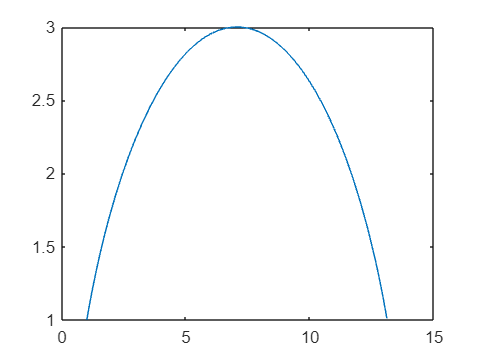

plot(tSol,R)

## Task 1 (continued)

Define the ODE function for   where  and  

function dYdt=expandingUniverse(t,Y)
R=Y(1);
v=Y(2);
omegaM=0.3;
omegaDE=0.7;
dRdt=v;
dvdt=-0.5.*omegaM/R^2+omegaDE*R;
dYdt=[dRdt;dvdt];
end

## Task 2 (continued)

Define the ODE function for   where  and  

function dYdt=contractingUniverse(t,Y)
R=Y(1);
v=Y(2);
omegaM=01.5;
omegaDE=0;
dRdt=v;
dvdt=-0.5.*omegaM/R^2+omegaDE*R;
dYdt=[dRdt;dvdt];
end